# Windfarm Processing

Processing of the windfarm database consists of filtering the data, adding powercurve, and adding missing data

## Load Windturbine Data

filename = 'TheWindPowerDatabaseWithRotorParameters25Mar.csv';
opts = detectImportOptions(['WT_data\' filename],'Encoding','UTF-8');
t=readtable(['WT_data\' filename],opts);

## Basic Filtering

Remove offshore turbine

t(~strcmp(t.Offshore_Shore_distance,'No'),:)=[];

Remove turbine not in production (i.e.,  Construction, Planned, Approved or dismantled)

t(~strcmp(t.Status,'Production'),:)=[];

Remove data without location information

t(isnan(t.Latitude) | isnan(t.Longitude),:)=[];

Remove data outside of study area as defined by the bird datase. First, we assign to each windfarm the grid id of its location in the bird database and  then we filter for windfarm further than 50km from the closest grid id. 

load('../2018/data/Density_estimationMap','g');
[dist,grid_id] = min(pdist2([g.lat2D(g.latlonmask) g.lon2D(g.latlonmask)],[t.Latitude t.Longitude],@lldistkm));
t.grid_id = grid_id';
t(dist>50,:)=[];

Display table

t

t = 12518×34 table
     ID      Continent    ISO_code     Country     State_code              Area                        City                    Name              X2nd_name        Latitude    Longitude    Altitude_Depth    Location_accuracy    Offshore_Shore_distance    Manufacturer       Turbine        Hub_height    Number_of_turbines    Total_power                    Developer                                   Operator                                      Owner                       Commissioning_date       Status       Decommissioning_date     Link

## Load Power Curve data

filename = 'Power_curves_20210319.xls';
opts = detectImportOptions(['WT_data\' filename],'Sheet','Power_curves');
tp=readtable(['WT_data\' filename],opts);
powerCurve.ws = table2array(tp(1,6:end-2));
powerCurve.ManufucturerName = tp.ManufucturerName(2:end);
powerCurve.TurbineName = tp.TurbineName(2:end);
powerCurve.Power = table2array(tp(2:end,6:end-2));

## **Smoothing Powercurve**

0.2+0.1*w (Jourdier, 2020 ; 10.5194/asr-17-63-2020): 30 min

0.6 + 0.2*w (Staffell & Pfenninger 2016 ; 10.1016/j.energy.2016.08.068) : 1hr MERRA

1.0 (Olauson & Bergkvist, 2015) 1hr MERRA

1.5 (Olauson, 2018)

powerCurve.ws_smooth=powerCurve.ws(1):0.1:powerCurve.ws(end);
powerCurve.Power_smooth = nan(size(powerCurve.Power,1),numel(powerCurve.ws_smooth));

for i_p=1:size(powerCurve.Power,1)
    p = interp1(powerCurve.ws,powerCurve.Power(i_p,:),powerCurve.ws_smooth);
    % figure; plot(powerCurve.ws,powerCurve.Power(i_p,:),'or',powerCurve.ws_smooth,p,'-k')
    for i_w=1:numel(powerCurve.ws_smooth)
        s = 0.6+0.2*powerCurve.ws_smooth(i_w);
        weight = normpdf(powerCurve.ws_smooth,powerCurve.ws_smooth(i_w),s); 
        weight = weight ./sum(weight);
        powerCurve.Power_smooth(i_p,i_w)=weight*p'; 
    end
    % figure; hold on; plot(powerCurve.ws,powerCurve.Power(i_p,:)); plot(powerCurve.ws_smooth,powerCurve.Power_smooth(i_p,:)); 
end

## Add Powercurve to windturbine

[~,Locb] = ismember(string([t.Turbine t.Manufacturer])  , string([powerCurve.TurbineName powerCurve.ManufucturerName]),'rows');
% t2=t(Locb==0,:);
t.powerCurve = nan(size(t,1),numel(powerCurve.ws_smooth));
t.powerCurve(Locb~=0,:) = powerCurve.Power_smooth(Locb(Locb~=0),:);

It would be nicer to do use the join function, but thes function requires that all windfarms have a matching powercurve. Hence, we use ismemeber()

%t2=join(t,tp,'LeftKeys','ID','RightKeys','Turb_ID');

## Assessed missing data

a=sprintf([num2str(size(t,1)) '\t windfarms\n' ]);
a=[a sprintf([num2str(sum(isnan(t.Number_of_turbines))) '\t windfarms without number of windturbine\n' ])];
a=[a sprintf([num2str(sum(isnan(t.turbine_sweptArea))) '\t windfarms without swept area\n' ])];
a=[a sprintf([num2str(sum(isnan(t.Hub_height))) '\t windfarms without hub height\n' ])];
a=[a sprintf([num2str(sum(all(isnan(t.powerCurve),2))) '\t windfarms without power curve\n' ])];
disp(a)

12518	 windfarms
154	 windfarms without number of windturbine
166	 windfarms without swept area
166	 windfarms without hub height
3259	 windfarms without power curve



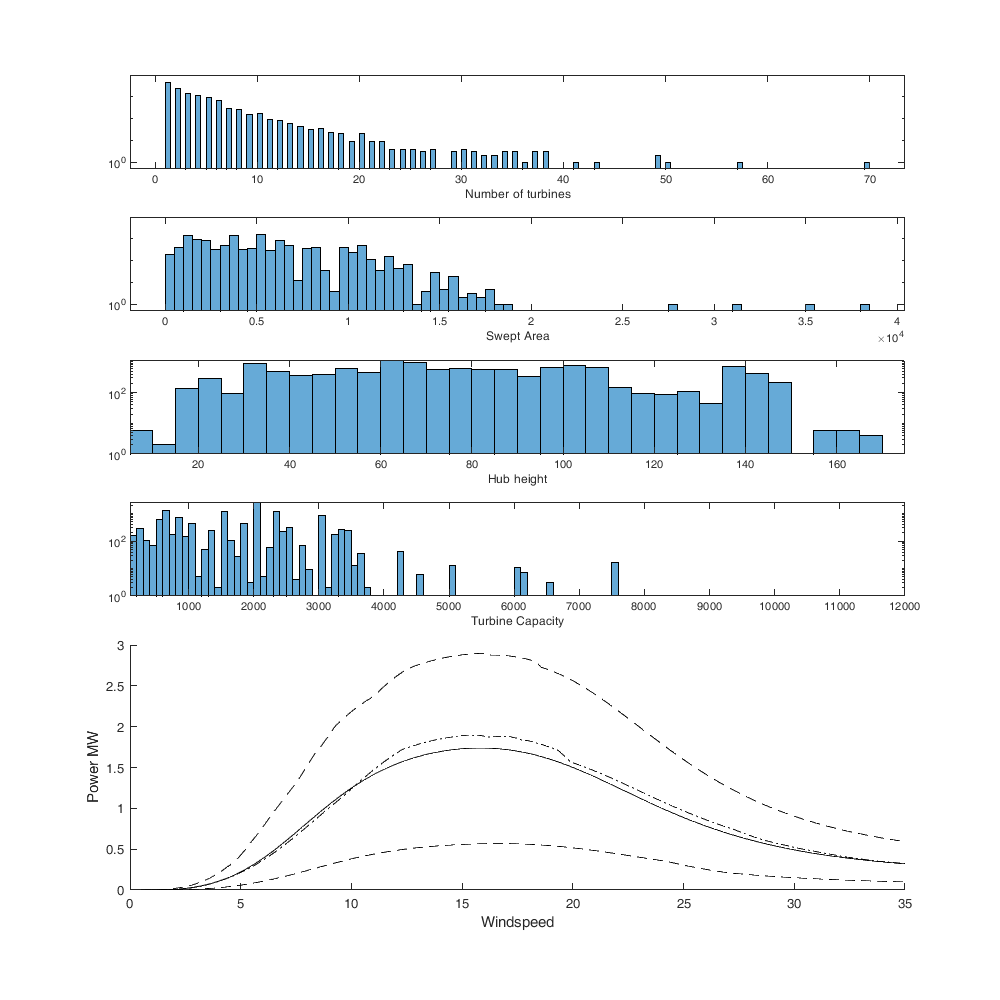

figure('position',[0 0 1000 1000]); 
subplot(6,1,1); histogram(t.Number_of_turbines); xlabel('Number of turbines'); ylim([0.5 10000]);set(gca, 'YScale', 'log')
subplot(6,1,2); histogram(t.turbine_sweptArea); xlabel('Swept Area'); ylim([0.5 10000]); set(gca, 'YScale', 'log')
subplot(6,1,3); histogram(t.Hub_height); xlabel('Hub height'); axis tight;set(gca, 'YScale', 'log')
subplot(6,1,4); histogram(t.turbine_capacity); xlabel('Turbine Capacity'); axis tight;set(gca, 'YScale', 'log')
subplot(6,1,[5 6]); hold on;
plot(powerCurve.ws_smooth, nanmean(t.powerCurve/1000),'k');
plot(powerCurve.ws_smooth, nanmedian(t.powerCurve/1000),'-.k');
plot(powerCurve.ws_smooth, quantile(t.powerCurve/1000,0.1),'--k');
plot(powerCurve.ws_smooth, quantile(t.powerCurve/1000,.9),'--k'); 
ax=gca; ylabel('Power MW'); xlabel('Windspeed')

## Fill gaps

Several method exist for missing data: median, GLM or kNN (or more sofisticated like MICE)

First, we explore relationships between the variable of interest to see which variable can be used, and what kind of relationship there are among them

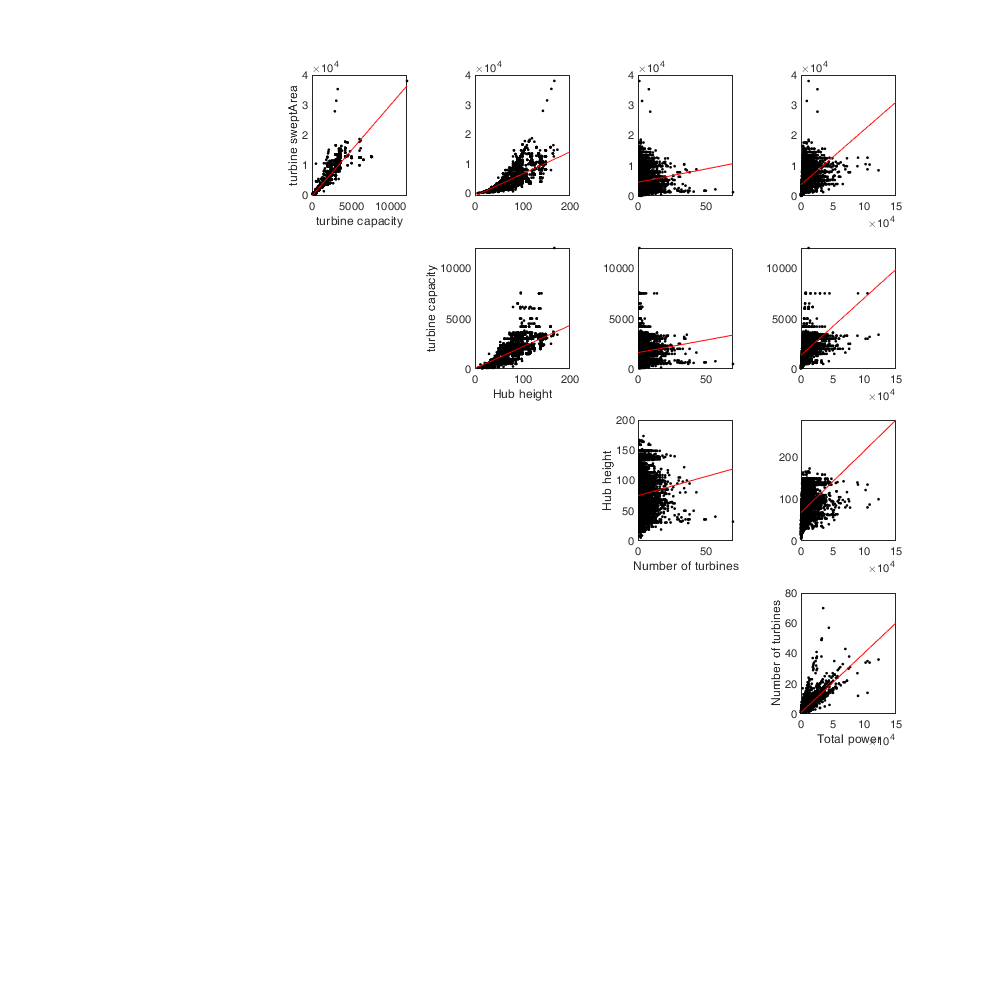

var_test = {'turbine_sweptArea','turbine_capacity','Hub_height','Number_of_turbines','Total_power'};
figure('position',[0 0 1000 1000]); 
for i1=1:numel(var_test)
    for i2=(i1+1):numel(var_test)
        subplot(numel(var_test),numel(var_test),i2+(i1-1)*numel(var_test)); hold on
        plot(t.(var_test{i2}),t.(var_test{i1}),'.k'); 
        if i2==i1+1, xlabel(strrep(var_test{i2},'_',' ')); ylabel(strrep(var_test{i1},'_',' ')); end
        l=lsline; l.Color='r'; 
        box on;
    end
end

Based on this plot, we can see that turbine_sweptArea, turbine_capacity and Hub_height are linearly linked while Total_power and number of turbines are also linked

We then use  GLMs to predict the data and created a table with imputated value tim

tim=t;

Check occurane of nan for the three variable

X=[tim.turbine_sweptArea tim.turbine_capacity tim.Hub_height];
[a1,~,c] = unique(isnan(X),'rows');
[a1 histcounts(c)']

ans =            0           0           0       12350
           0           1           0           2
           1           1           1         166


Hub height can be determined from swept area and turbine capacity for 4K cases, the other variable can only be estimated in 1 case... (so not useful)

We build a glm with all the data and predict only for nan value in Hub_height: 

mdl = fitglm([tim.turbine_sweptArea tim.turbine_capacity],tim.Hub_height);
[ypred,yci] = predict(mdl,[tim.turbine_sweptArea(isnan(tim.Hub_height),:) tim.turbine_capacity(isnan(tim.Hub_height),:)]);
ypred(ypred>max(tim.Hub_height))=max(tim.Hub_height); % Avoid missleading value of hubheight
tim.Hub_height(isnan(tim.Hub_height)) = ypred;

We performe the same analysis for Number_of_turbines and Total_power

Check occurane of nan

X=[tim.Number_of_turbines tim.Total_power];
[a1,~,c] = unique(isnan(X),'rows');
[a1 histcounts(c)']

ans =            0           0       12350
           0           1          14
           1           0         153
           1           1           1


We performe the prediction for both variable as above

mdl = fitglm(tim.Number_of_turbines, tim.Total_power);
mdl2 = fitglm(tim.Total_power,tim.Number_of_turbines);
[ypred,yci] = predict(mdl,tim.Number_of_turbines(isnan(tim.Total_power),:));
tim.Total_power(isnan(tim.Total_power)) = ypred;
[ypred,yci] = predict(mdl2,tim.Total_power(isnan(tim.Number_of_turbines),:));
tim.Number_of_turbines(isnan(tim.Number_of_turbines)) = ypred;

We can then assess the missing value in the new imputated table

a=sprintf([num2str(size(tim,1)) '\t windfarms\n' ]);
for i=1:numel(var_test)
    a=[a sprintf([num2str(sum(isnan(tim.(var_test{i})))) '\t windfarms without ' var_test{i} '\n' ])];
end
disp(a)

12518	 windfarms
166	 windfarms without turbine_sweptArea
168	 windfarms without turbine_capacity
166	 windfarms without Hub_height
1	 windfarms without Number_of_turbines
1	 windfarms without Total_power



The remaining missing data can be filled with the median value. 

% tim=t; % in case GLM is not used above
for i=1:numel(var_test)
    tim.(var_test{i})(isnan(tim.(var_test{i})))=nanmedian(tim.(var_test{i}));
end

Fill also powercurve with median. Not used anymore, see below

% tmp = all(isnan(tim.powerCurve),2);
% tim.powerCurve(tmp,:) = repmat(nanmedian(tim.powerCurve),sum(tmp),1);

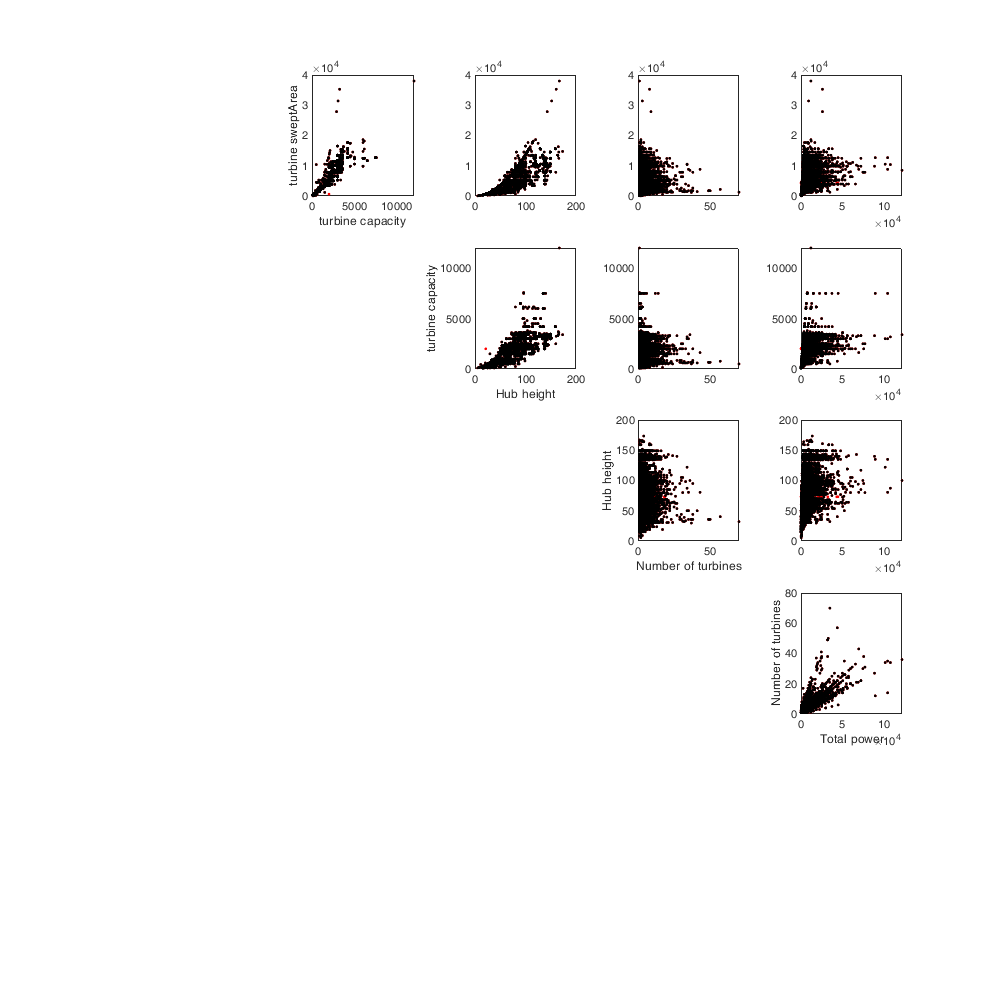

var_test = {'turbine_sweptArea','turbine_capacity','Hub_height','Number_of_turbines','Total_power'};
figure('position',[0 0 1000 1000]); 
for i1=1:numel(var_test)
    for i2=(i1+1):numel(var_test)
        subplot(numel(var_test),numel(var_test),i2+(i1-1)*numel(var_test)); hold on
        plot(tim.(var_test{i2}),tim.(var_test{i1}),'.r'); 
        plot(t.(var_test{i2}),t.(var_test{i1}),'.k');
        if i2==i1+1, xlabel(strrep(var_test{i2},'_',' ')); ylabel(strrep(var_test{i1},'_',' ')); end
        box on;
    end
end

Fill missing powerCurve

We parametrize the function with its max value: its position and its amount

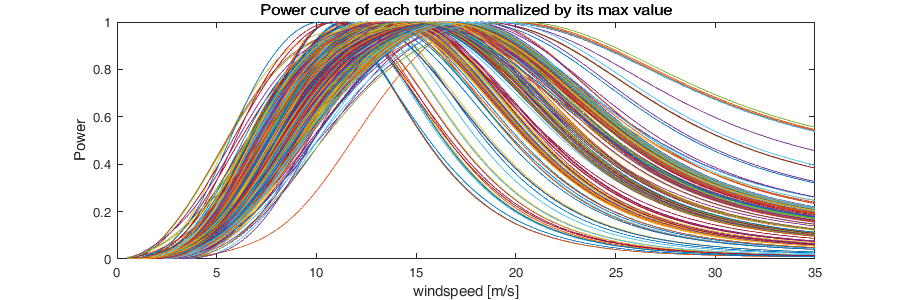

figure('position',[0 0 900 300]); 
plot(powerCurve.ws_smooth,(powerCurve.Power_smooth'./max(powerCurve.Power_smooth,[],2)'))
xlabel('windspeed [m/s]'); ylabel('Power'); title('Power curve of each turbine normalized by its max value')

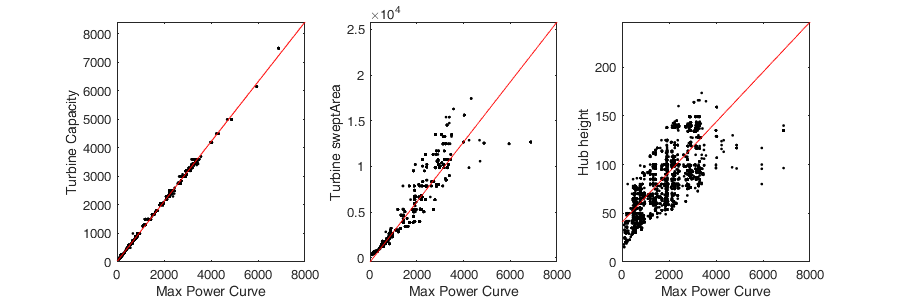

[maxTimPower,maxTimPowerID] = max(t.powerCurve,[],2); maxTimPowerID(maxTimPowerID==1)=nan; % maxTimPowerID==1 is when there are no data
figure('position',[0 0 900 300]); 
subplot(1,3,1);plot(maxTimPower,tim.turbine_capacity,'.k');l=lsline; l.Color='r'; xlabel('Max Power Curve'); ylabel('Turbine Capacity')
subplot(1,3,2);plot(maxTimPower,tim.turbine_sweptArea,'.k');l=lsline; l.Color='r'; xlabel('Max Power Curve'); ylabel('Turbine sweptArea')
subplot(1,3,3);plot(maxTimPower,tim.Hub_height,'.k');l=lsline; l.Color='r'; xlabel('Max Power Curve'); ylabel('Hub height')

The Max Power Curve value is well related to the three turbine caracteristic. We can use again a GLM for fill the missing value. 

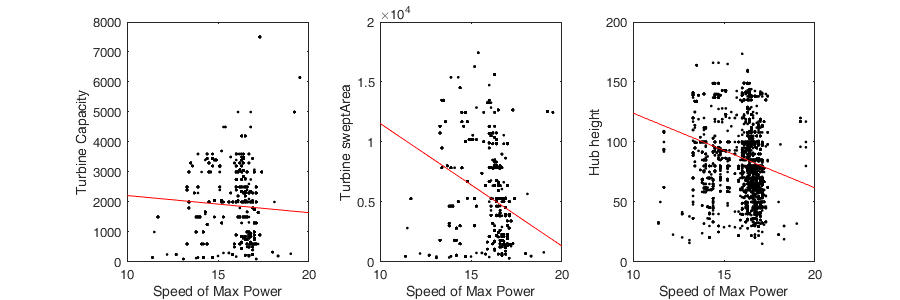

figure('position',[0 0 900 300]); 
subplot(1,3,1);plot(powerCurve.ws_smooth(maxTimPowerID(~isnan(maxTimPowerID))),tim.turbine_capacity(~isnan(maxTimPowerID)),'.k');l=lsline; l.Color='r'; xlabel('Speed of Max Power'); ylabel('Turbine Capacity')
subplot(1,3,2);plot(powerCurve.ws_smooth(maxTimPowerID(~isnan(maxTimPowerID))),tim.turbine_sweptArea(~isnan(maxTimPowerID)),'.k');l=lsline; l.Color='r'; xlabel('Speed of Max Power'); ylabel('Turbine sweptArea')
subplot(1,3,3);plot(powerCurve.ws_smooth(maxTimPowerID(~isnan(maxTimPowerID))),tim.Hub_height(~isnan(maxTimPowerID)),'.k');l=lsline; l.Color='r'; xlabel('Speed of Max Power'); ylabel('Hub height')

However, there are no clear value for the location of the max power... we can simply use the median

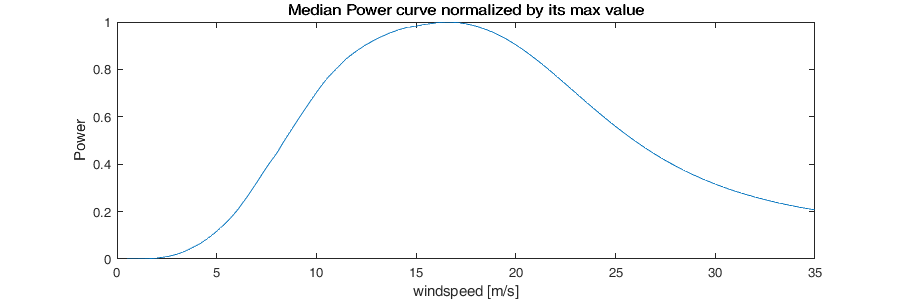

powerCurve_template = nanmedian(tim.powerCurve'./max(tim.powerCurve,[],2)',2);
figure('position',[0 0 900 300]); 
plot(powerCurve.ws_smooth,powerCurve_template)
xlabel('windspeed [m/s]'); ylabel('Power'); title('Median Power curve normalized by its max value')

Use GLM to find max powercurve

X=[tim.turbine_sweptArea tim.turbine_capacity tim.Hub_height];
mdl = fitglm(X,max(tim.powerCurve,[],2) );
[ypred,yci] = predict(mdl,X(isnan(max(t.powerCurve,[],2)),:));
% ypred(ypred>max(tim.powerCurve(:)))=max(tim.powerCurve(:));
tim.powerCurve(isnan(max(tim.powerCurve,[],2)),:) = powerCurve_template' .* ypred;

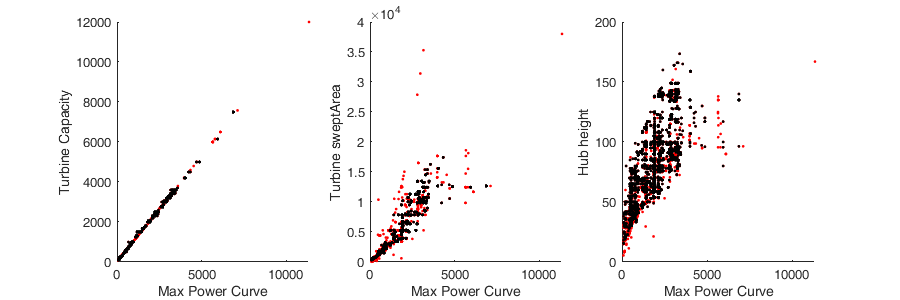

[maxTimPowert,~] = max(t.powerCurve,[],2);
[maxTimPower,~] = max(tim.powerCurve,[],2);
figure('position',[0 0 900 300]); 
subplot(1,3,1);hold on; plot(maxTimPower,tim.turbine_capacity,'.r'); plot(maxTimPowert,t.turbine_capacity,'.k'); xlabel('Max Power Curve'); ylabel('Turbine Capacity')
subplot(1,3,2);hold on; plot(maxTimPower,tim.turbine_sweptArea,'.r');plot(maxTimPowert,t.turbine_sweptArea,'.k'); xlabel('Max Power Curve'); ylabel('Turbine sweptArea')
subplot(1,3,3);hold on; plot(maxTimPower,tim.Hub_height,'.r'); plot(maxTimPowert,t.Hub_height,'.k'); xlabel('Max Power Curve'); ylabel('Hub height')

## Add Energy

Load wind data

file='./ECMWF/2018_srf.nc'; %ncdisp(file);
wind.time = datetime('2018-01-01 00:00'):1/24:datetime('2018-12-31 23:00'); % ncread(file,'time')
wind.latitude=flip(double(ncread(file,'latitude')));
wind.longitude=double(ncread(file,'longitude'));
wind_u100 = permute(flip(ncread(file,'u100'),2) , [2 1 3]); 
wind_v100 = permute(flip(ncread(file,'v100'),2) , [2 1 3]);
wind.hundread = sqrt(wind_u100.^2  + wind_v100.^2);
wind_u10 = permute(flip(ncread(file,'u10'),2) , [2 1 3]); 
wind_v10 = permute(flip(ncread(file,'v10'),2) , [2 1 3]);
wind.ten = sqrt(wind_u10.^2  + wind_v10.^2);

**Interpolate**

Spatial interpolation at 100 and 10m

F_hundread = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time)},wind.hundread,'linear','nearest');
w_hundread = F_hundread(repmat(tim.Latitude,1,numel(wind.time)), repmat(tim.Longitude,1,numel(wind.time)), repmat(datenum(wind.time),size(tim,1),1));

F_ten = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time)},wind.ten,'linear','nearest');
w_ten = F_ten(repmat(tim.Latitude,1,numel(wind.time)), repmat(tim.Longitude,1,numel(wind.time)), repmat(datenum(wind.time),size(tim,1),1));

Vertical interpolation

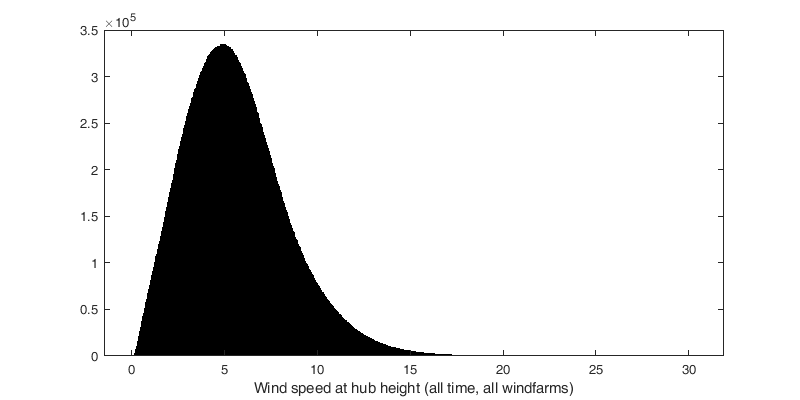

alpha = (log(w_hundread)-log(w_ten)) ./ (log(100)-log(10));
w_height = w_hundread .* (tim.Hub_height /100).^alpha;
figure('position',[0 0 800 400]); histogram(w_height); xlabel('Wind speed at hub height (all time, all windfarms)')

% figure; plot(wind.time, mean(t_height));

**Compute Power**

Compute the power equivalent of each windfarm and each timestep (still on the ERA5 time resolution 1hr).

We use a small trick to match the windspeed with the equivalent power production by using the fact that the power production is set on a regular windspeed grid (`powerCurve.ws_smooth`) which is 0:0.1:35.  So, we can find for each `windspeed (t_height)`, the index in the powercurve table (tim.`power)`, using: 

w_height_r = round(w_height,1); % round to the resolution of the windspeed 0.1
index = uint16(w_height_r*10+1); % 0.1 resolution -> 1 resolution , and +1 to get index 0 to 1.

We can then loop through each windfarm and get the power equivalent using this index

power = nan(size(w_height));
for i_t = 1:size(w_height,1)
    power(i_t,:) = tim.powerCurve(i_t,index(i_t,:)).*tim.Number_of_turbines(i_t);
end

Visualization

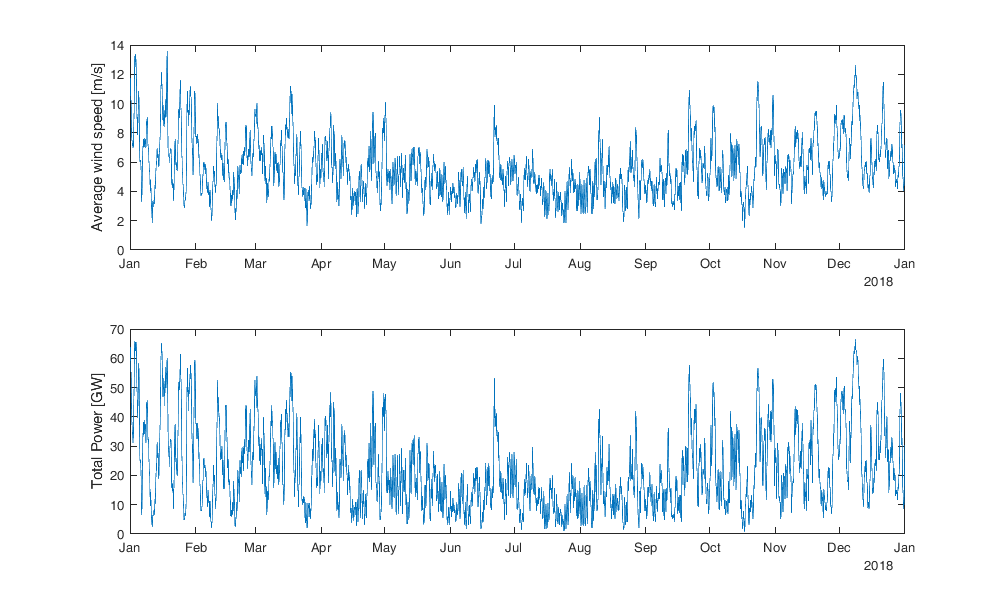

figure('position',[0 0 1000 600]);
subplot(2,1,1); plot(wind.time, mean(w_height)); ylabel('Average wind speed [m/s]')
subplot(2,1,2); plot(wind.time, sum(power*1000/1e9)); ylabel('Total Power [GW]')

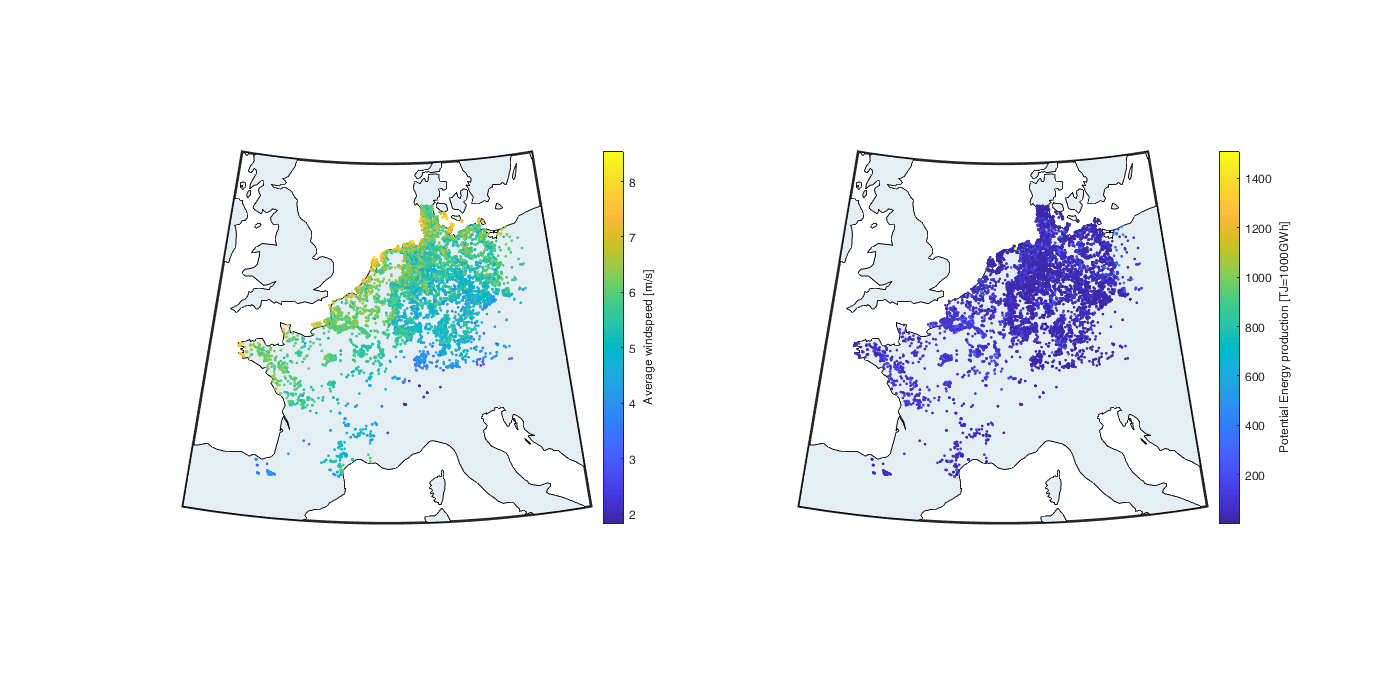

figure('position',[0 0 1400 700]); 
subplot(1,2,1); hold on;
h = worldmap([min(tim.Latitude)-2 max(tim.Latitude)+2], [min(tim.Longitude)-2 max(tim.Longitude)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
% surfm(g.lat,g.lon,turbineSweptAreaMap)
scatterm(tim.Latitude,tim.Longitude,[],nanmean(w_height,2),'.');
c=colorbar; c.Label.String='Average windspeed [m/s]';
subplot(1,2,2); hold on;
h = worldmap([min(tim.Latitude)-2 max(tim.Latitude)+2], [min(tim.Longitude)-2 max(tim.Longitude)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
% surfm(g.lat,g.lon,turbineSweptAreaMap)
scatterm(tim.Latitude,tim.Longitude,[],sum(power*1000*60*60/1e12,2),'.'); % caxis([0 100]);
c=colorbar; c.Label.String='Potential Energy production [TJ=1000GWh]';

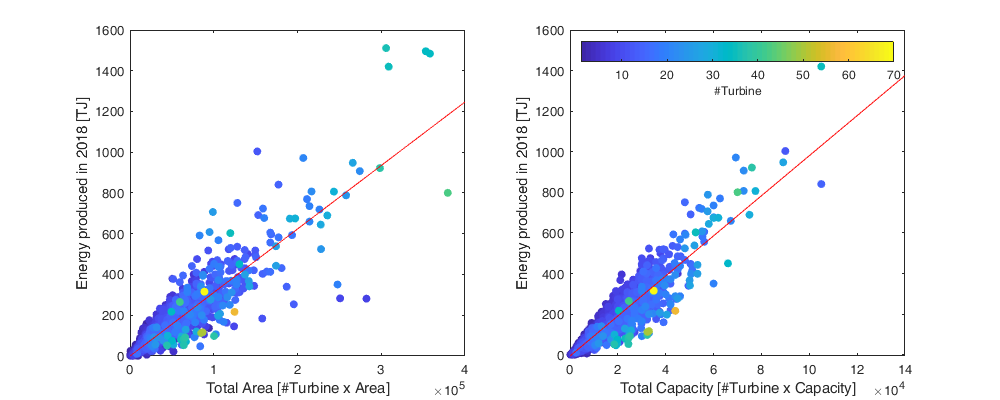

tmp = sum(power*1000*60*60/1e12,2);
[~,id]=sort(tim.Number_of_turbines);
figure('position',[0 0 1000 400]); 
subplot(1,2,1); hold on;
scatter(tim.Number_of_turbines(id).*tim.turbine_sweptArea(id),tmp(id),[],tim.Number_of_turbines(id),'filled');
l=lsline; l.Color='r'; box on
xlabel('Total Area [#Turbine x Area]'); 
ylabel('Energy produced in 2018 [TJ]')
subplot(1,2,2);  hold on;
scatter(tim.Number_of_turbines(id).*tim.turbine_capacity(id),tmp(id),[],tim.Number_of_turbines(id),'filled');
l=lsline; l.Color='r'; box on
c=colorbar('north'); c.Label.String='#Turbine';
xlabel('Total Capacity [#Turbine x Capacity]'); 
ylabel('Energy produced in 2018 [TJ]')

## Save

time = wind.time;
save('data/windfarms_processed.mat', 'tim', 'power', 'time')